# Lista 1 - Parte 2a

Autor: Francisco Castro

## Introdução

    Este documento refere-se à navegação inercial com dados reais de sensores solidários, sendo a continuação (parte 2) da primeira lista computacional já entregue como atividade da disciplina EES-60, ministrada pelo Prof. Dr. Jacques Waldmann em 2019.

    Seu objetivo é a integração numérica das equações diferenciais de atitude com quaternion relativo e de navegação inercial usando dados reais de IMUs de classe inercial e de classe comercial (COTS – *commercial off-the-shelf*).

    A primeira subparte (2a) da lista refere-se aos dados dos sensores IMU fornecidos no arquivo *dados.dat*, correspondentes à montanha russa Montezum. A segunda subparte (2b), refere-se aos dados disponíveis no arquivo *SN500574Outside.m*.

## Método TRIAD

    Primeiramente, executa-se os procedimentos realizados na parte 1a desde exercícios computacional, referentes ao método TRIAD para determinação das condições iniciais que servirão de base para a integração das equações de atitude e de navegação a seguir.

metodoTRIAD;

## Integração numérica

    Utilizar-se-á, neste momento, um algoritmo de integração numérica Runge–Kutta de 4ª ordem com passo fixo para integrar as equações de atitude com quatérnions e de navegação inercial utilizando dados já carregados na Parte 1a desta lista, mas de forma a simular uma aquisição em tempo real.

**Condições iniciais**

    Tendo o quatérnion $q^{NED}_{B,comp} = q_0$, advindo do método TRIAD, que determina a orientação inicial do corpo com relação ao NED, podemos definir o vetor de estados 


$$y = [q^{NED}_{B,comp}, V_{NED}, \lambda, \Lambda, h, h_m]^T$$


 característico da integração numérica, cuja dimensão é 7x1.

y = [
        q0_base3;
        [0,0,0]';
        lambda;
        Lambda;
        h;
        h
    ];

onde a base 3 é a base ortonormal com a qual foi construída o quatérnion na Parte 1a desta lista.

**Condições de parada e variáveis de apoio**

tf = 19.5*60;               % tempo final
i0 = 1;                     % index do início do movimento
i = i0;                     % index inicial
freqAquisicao = 100;        % Hz
p = 1/freqAquisicao;        % passo de integração
result = zeros(tf/p,length(y)+2);

**Função dinâmica**

    Define-se a função dinâmica **f** que implementa as equações diferenciais que seguem:


$$\dot{q^{NED}_{B,comp}} = \frac{1}{2} (\Omega^{Bi}_{B,medido}+\Omega^{NEDi}_{NED,comp}) q^{NED}_{B,comp}\\

\dot{V_N} =         Asp_{NED,medido,N} + 
\frac{V_N}{(R_N + h)} V_D - 
\left(2 \Omega \sin(\lambda) + 
\frac{V_E}{(R_E + h)} \tan(\lambda)\right)V_E\\

\dot{V_E} =        Asp_{NED,medido,E} + 
\left(2 \Omega \sin(\lambda) + \frac{V_E}{(R_E + h)} \tan(\lambda)\right) V_N + 
\left(2 \Omega \cos(\lambda) + \frac{V_E}{(R_E + h)}\right)V_D\\

\dot{V_D} =        Asp_{NED,medido,D} - 
\left(2 \Omega \cos(\lambda) + \frac{V_E}{(R_E + h)}\right) V_E - \frac{V_N}{(R_N + h)} V_N + g + B(h-h_{aux})\\

\dot{\lambda} =         \frac{V_N}{(R_N + h)}\\

\dot{\Lambda} =        \frac{V_E}{(R_E + h) \cos(\lambda)}\\

\dot{h} =        -V_D - C(h - h_{aux})\\
\dot{h_{aux}} = \frac{h_m-h_{aux}}{T_h}$$


conforme descrito no roteiro desta atividade e no material do curso, tendo, com isso, a estrutura básica para a integração numérica pelo método escolhido, contando com a implementação da estabilização do canal vertical.

**Estabilização vertical**

    Para correto cômputo das expressões internas à função dinâmica **f**, define-se os parâmetros associados à estabilização do canal vertical como seguem.

h_m = h;            % constante e igual à altitude inicial
estabVert.B = 0.01;
estabVert.C = 0.01;
estabVert.T_h = 60;

**Modelamento da Terra e da gravidade**

    Os parâmetros associados ao modelamento da Terra e da gravidade, $R_0$, $e$ e $g_0$ já foram definidos na chamada do Método TRIAD e são os que constam.

modTerra.R_0 = R_0; % [m]
modTerra.g_0 = g_0; % [m/s^2]
modTerra.e = e;     % achatamento

    A saber

modTerra

modTerra = struct with fields:
    R_0: 6378138
    g_0: 9.7803
      e: 0.0033529


**Runge-Kutta**

    Com isso, a integração numérica propriamente dita fica

for t=0:p:tf
    omega_B_i = w_b(i,:)';  % retirado dos dados a cada passo
    Asp_B_i = Asp_b(i,:)';  % idem
    
    k1 = f(t, y, omega_B_i, Asp_B_i, modTerra, estabVert, h_m);
    k2 = f(t + p/2, y + p/2*k1, omega_B_i, Asp_B_i, modTerra, estabVert, h_m);
    k3 = f(t + p/2, y + p/2*k2, omega_B_i, Asp_B_i, modTerra, estabVert, h_m);
    k4 = f(t + p, y + p*k3, omega_B_i, Asp_B_i, modTerra, estabVert, h_m);

    y = y + p/6*(k1 + 2*k2 + 2*k3 + k4);
    result(i-i0+1,1) = t;       % tempo
    result(i-i0+1,2:12) = y;    % vetor de estados
    i = i+1;
end

## Resultados

    Com isso, tem-se o seguinte resultado imediato da integração numérica

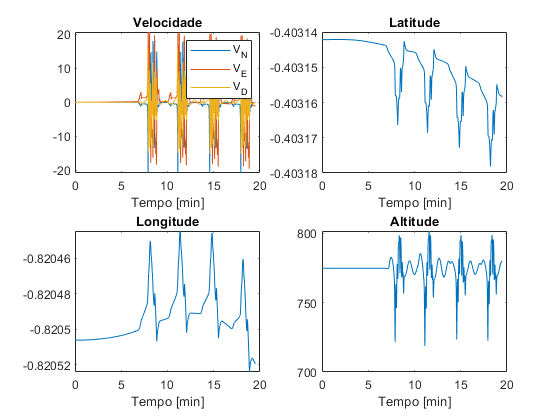

preProcessResults

da onde tira-se os valores aproximados para os intervalos de tempo para cada volta, apresentados na Tabela 01, a partir do instante 0 [s].

**Tabela 01.** Marcação de tempo e duração de cada volta

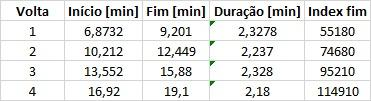

## Análise da atitude computada pelo INS

**Vetor rotação**

    Calculou-se o vetor rotação ao final de cada volta com relação ao vetor original $q0$, em [arcseg], de forma que

format shortG;
rotacaoFinalDeVolta = [
vetorRotacao(resultados.quaternion(indexFim.volta1,:), q0_base3),...
vetorRotacao(resultados.quaternion(indexFim.volta2,:), q0_base3),...
vetorRotacao(resultados.quaternion(indexFim.volta3,:), q0_base3),...
vetorRotacao(resultados.quaternion(indexFim.volta4,:), q0_base3)...
]*180/pi*3600

rotacaoFinalDeVolta =       -13.262      -38.002      -17.112      -97.941
      -33.944      -60.376      -36.276      -2202.8
       2.3014      -148.22      -262.86      -760.87


**Índice de desalinhamento ao final de cada volta (escala log)**

    Analogamente, temos que os índices de desalinhamento dos quatérnions ao final de cada volta com relação ao quatérnion inicial $q_0$ são dados, em [arcseg], por

indiceDesalFinalDeVolta = [
indiceDesalinhamento(resultados.quaternion(indexFim.volta1,:), q0_base3),...
indiceDesalinhamento(resultados.quaternion(indexFim.volta2,:), q0_base3),...
indiceDesalinhamento(resultados.quaternion(indexFim.volta3,:), q0_base3),...
indiceDesalinhamento(resultados.quaternion(indexFim.volta4,:), q0_base3)...
]*180/pi*3600

indiceDesalFinalDeVolta =        36.516       164.49       265.91       2332.5


Que se fazem valores naturalmente crescentes e cada vez mais significativos ao estado atual e, consequentemente, à amplificação dos erros futuros devido ao erro nas condições iniciais a ser imposto no processo de integração numérica.

**Comparação: índice de desalinhamento [arcseg] com magnitude do desalinhamento [arcseg] computado com quaternions**

normasRotacao = [
    norm(rotacaoFinalDeVolta(:,1)),...
    norm(rotacaoFinalDeVolta(:,2)),...
    norm(rotacaoFinalDeVolta(:,3)),...
    norm(rotacaoFinalDeVolta(:,4))...
    ];
format shortE
comparacao1 = normasRotacao - indiceDesalFinalDeVolta

comparacao1 =   -7.6925e-04  -3.4852e-04  -3.2554e-04  -5.0411e-05


De onde vê-se que há uma alta concordância entre as duas métricas escolhidas para avaliar o desallinhamento do quaternion atual com relação ao quaternion inicial para cada fim de volta.

**Comparação: índices de normalidade e desalinhamento ao final de cada volta com e sem normalização de quaternion ao longo da integração (escala log)**

comparacaoIndices;

comparacaoIndicesNormalidade =    2.7938e-08   5.5739e-08   8.5028e-08   1.1352e-07


comparacaoIndicesDesalinhamento =    4.7317e-04   2.1008e-04   1.9877e-04   2.7849e-05


Tais resultados nos dão um comparativo para cada final de volta (4 no total) do erro de não normalizar a cada passo de integração e a de desalinhamento devido a não normalidade. Vê-se que o preço a se pagar no desalinhamento é bem maior, em ordens de grandeza, do que o preço da não normalidade. O interessante é notar que o índice de desalinhamento diminui à medida que o índice de normalidade cresce, o que indica uma tendência do sistema a reduzir o erro de alinhamento com relação a condição inicial mesmo com o erro de normalidade aumentando.

## Análise da trajetória computada pelo INS

**Coordenadas geodésicas x cartesianas**

[xt,yt,zt] = geodToCart(...
    resultados.latitude,...
    resultados.longitude,...
    resultados.altitude,...
    modTerra);

**Resultado da altura contra tempo**

    Se tomada em relação ao ponto inicial, temos que a altura em função do tempo, em metros, pode ser dada por:

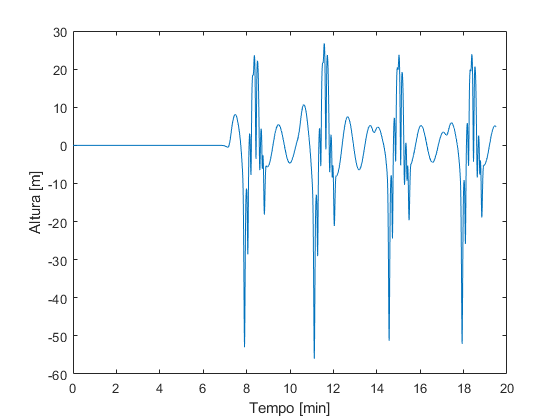

plot(resultados.tempo, zt)
xlabel("Tempo [min]");
ylabel("Altura [m]");

**Gráfico tri-dimensional da trajetória computada pelo INS**

     A trajetória estimada pelo INS em relação ao ponto inicial, em metros, nas direções Norte, Leste e altitude a partir do instante inicial 0[s], em relação ao ponto inicial, é tal que

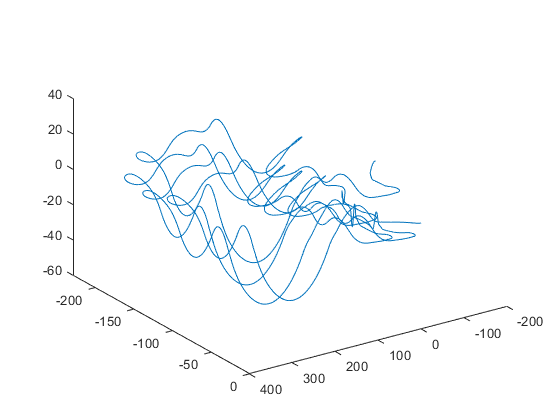

plot3(xt,yt,zt)
view([145.6 34.1]);

## Perguntas

**Quantas voltas há no primeiro experimento? Plote Norte contra Leste na primeira volta e superponha sobre a imagem (do Google Maps) de satélite da montanha russa Montezum do parque de diversões HopiHari em Vinhedo, SP, nas duas primeiras voltas e até o final do experimento. O que ocorre?**

    Há, no primeiro experimento, um total de 4 voltas. Que podem ser conferidas abaixo, onde se vê a superposição à foto real da montanha russa Montezum, retirada do Google Maps.

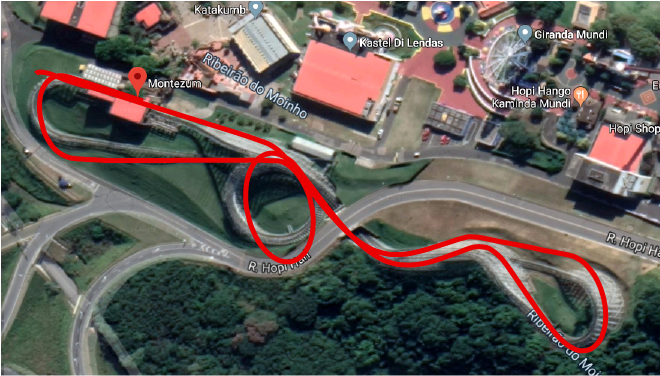

**Figura 05. **Superposição do resultado da integração numérica com a imagem real para a primeira volta.

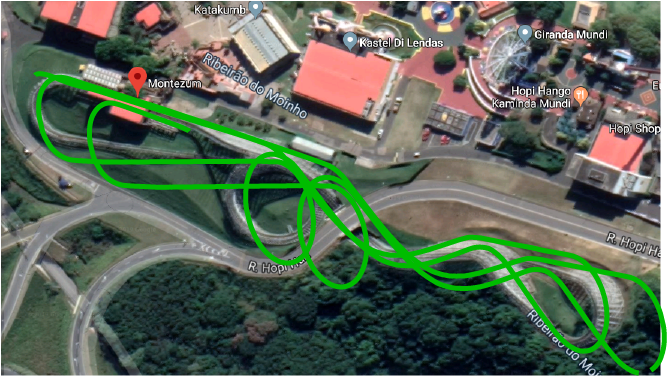

**Figura 06. **Superposição do resultado da integração numérica com a imagem real para as duas primeiras voltas.

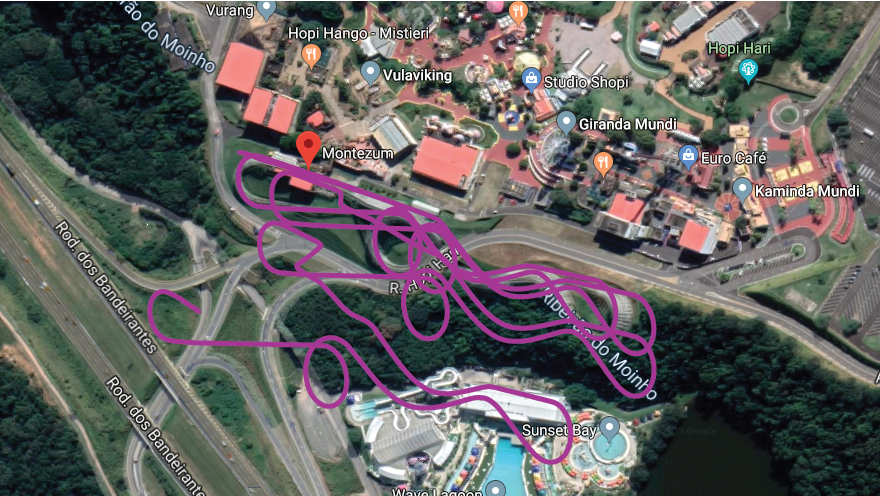

**Figura 07. **Superposição do resultado da integração numérica com a imagem real para as quatro voltas.

Observa-se, com isso, uma divergência crescente entre os resultados obtidos e o resultado esperado.

**Qual o erro de posição relativa ao ponto inicial no plano horizontal e em altura ao final da primeira volta no primeiro experimento?**

erroHorizontal = sqrt(xt(indexFim.volta1)^2 + yt(indexFim.volta1)^2)
erroAltura = zt(1)

erroHorizontal =        66.764


erroAltura =      0


Note que a estabilização vertical vai ocasionar um erro de altura pequeno a depender do ganho a se colocar no controlador.

**Ainda com respeito ao primeiro experimento, o que ocorre entre o final da primeira volta e o início da segunda volta? E nas demais voltas, isto é, entre o fim de uma volta anterior e o início da seguinte?**

    Entre o final da primeira volta e o início da segunda, bem como entre uma volta qualquer e a sua imediatamente anterior, há uma divergência de alinhamento (portanto, um desalinhamento) do corpo com relação ao quaternion inicial, o que provoca, à grosso modo, uma condição inicial ao movimento (pois o vagão para e depois volta a se mexer) diferente da inicial e sabidamente errada (desalinhada). Tal erro, somado ao já erro de posicionamento advindo da integração da volta anterior, causa uma divergência cada vez maior do desallinhamento e da posição com relação a mesma no "mesmo instante" da volta anterior.

**O que ocorre com a navegação inercial usando a IMU baseada em sensores MEMS do Xsens?**

Há notavelmente baixa precisão e erros sistemáticos que, por si sós, já ocasionam grandes erros de posicionamento e desalinhamento principalmente em operações com uma grande duração, mesmo que a estimativa das condições iniciais sejam muito boas.